# W02_Rover_Drivetrain_Analysis

Aido Rover drive-train kinematics, static anti-tipping and ground pressure.

Author: Xiaolei Jia Programme: InGen Dynamics Mechanical Engineer Internship

SOURCE DATA Aido Rover Detailed Functionality Specification, March 2026: Overall dimensions: 3.45 m x 1.88 m x 1.71 m Unloaded mass: 395 kg Maximum stated mass with full sensor configuration: 435 kg Drive: four-wheel independent electric drive and independent suspension Turning capability: 0 m centre turning radius Incline capability: 30 deg sustained, 35 deg momentary

ESTIMATED GEOMETRY Wheelbase: 2.50 m Track width: 1.60 m Wheel diameter: 0.65 m CoM height: 0.70 m Contact patch per wheel: 0.25 m x 0.15 m

IMPORTANT LIMITATIONS The ideal skid-steer model neglects lateral slip, tyre deformation, suspension compliance and terrain sinkage. The 150 kg payload-capacity statement is not added to the 435 kg configuration because the source document does not clearly define whether the values are additive.

clear; clc; close all;

## 1. Define platform parameters

g = 9.81;                 % gravitational acceleration, m/s^2
m_unloaded = 395;    % kg, confirmed
m_max = 435;             % kg, confirmed full-sensor configuration
L_body = 3.45;       % m, confirmed overall length
W_body = 1.88;        % m, confirmed overall width
H_body = 1.71;       % m, confirmed overall height

L = 2.5;          % m, estimated wheelbase
B = 1.6;         % m, estimated track width
r_wheel = 0.325;   % m, estimated wheel radius
h_CoM = 0.7;      % m, estimated centre-of-mass height

contact_width = 0.25;   % m, assumed
contact_length = 0.15; % m, assumed
A_contact = contact_width * contact_length;

fprintf('Aido Rover maximum modelled mass: %.1f kg\n', m_max);

Aido Rover maximum modelled mass: 435.0 kg


fprintf('Estimated wheelbase / track width: %.2f m / %.2f m\n', L, B);

Estimated wheelbase / track width: 2.50 m / 1.60 m


## 2. Ideal skid-steer / differential-drive model

vR is fixed at 1.0 m/s and vL is varied. The geometric relations are: centre speed = (vR + vL)/2 yaw rate = (vR - vL)/B centre turning radius = centre speed/yaw rate

Verification: vL = vR -> straight motion and infinite radius vL = -vR -> zero centre speed and zero-radius rotation

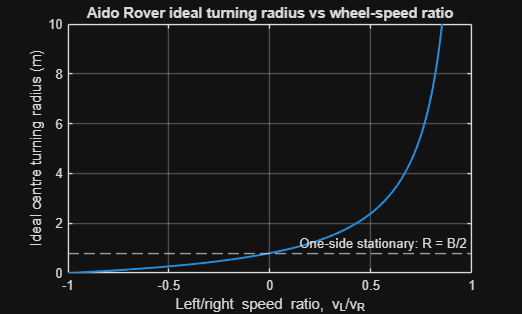

vR = 1.0;
ratio = linspace(-1.0, 0.95, 300);
vL = ratio .* vR;
v_centre = (vR + vL) ./ 2;
yaw_rate = (vR - vL) ./ B;
R_turn = v_centre ./ yaw_rate;

figure;
plot(ratio, R_turn, 'LineWidth', 1.5);
yline(B/2, '--', 'One-side stationary: R = B/2');
xlabel('Left/right speed ratio, v_L/v_R');
ylabel('Ideal centre turning radius (m)');
title('Aido Rover ideal turning radius vs wheel-speed ratio');
ylim([0 10]); grid on;


sample_ratio = [-1.00 -0.75 -0.50 -0.25 0 0.25 0.50 0.75 0.90]';
sample_vL = sample_ratio .* vR;
sample_v = (vR + sample_vL) ./ 2;
sample_omega = (vR - sample_vL) ./ B;
sample_R = sample_v ./ sample_omega;
turning_table = table(sample_ratio, repmat(vR,size(sample_ratio)), ...
    sample_vL, sample_v, sample_omega, sample_R, ...
    'VariableNames', {'vL_over_vR','vR_mps','vL_mps', ...
    'centre_speed_mps','yaw_rate_radps','centre_radius_m'});
disp(turning_table);

    vL_over_vR    vR_mps    vL_mps    centre_speed_mps    yaw_rate_radps    centre_radius_m
    __________    ______    ______    ________________    ______________    _______________

         -1         1          -1              0                1.25                  0    
      -0.75         1       -0.75          0.125              1.0938            0.11429    
       -0.5         1        -0.5           0.25              0.9375            0.26667    
      -0.25         1       -0.25          0.375             0.78125               0.48    
          0         1           0            0.5               0.625                0.8    
       0.25         1        0.25          0.625             0.46875             1.3333    
        0.5         1         0.5           0.75           


body_swept_radius = sqrt((L_body/2)^2 + (W_body/2)^2);
fprintf('In-place centre turning radius: 0 m\n');

In-place centre turning radius: 0 m


fprintf('Body swept radius during in-place rotation: %.3f m\n', body_swept_radius);

Body swept radius during in-place rotation: 1.964 m


fprintf('Required clear swept diameter: %.3f m\n', 2*body_swept_radius);

Required clear swept diameter: 3.929 m


## 3. Static anti-tipping limits

Longitudinal limit uses half the wheelbase. Lateral limit uses half the track width. The vehicle mass cancels from the tipping-angle relation.

theta_long = atan((L/2)/h_CoM);
theta_lat = atan((B/2)/h_CoM);

fprintf('Theoretical longitudinal tipping limit: %.2f deg\n', rad2deg(theta_long));

Theoretical longitudinal tipping limit: 60.75 deg


fprintf('Theoretical lateral tipping limit: %.2f deg\n', rad2deg(theta_lat));

Theoretical lateral tipping limit: 48.81 deg


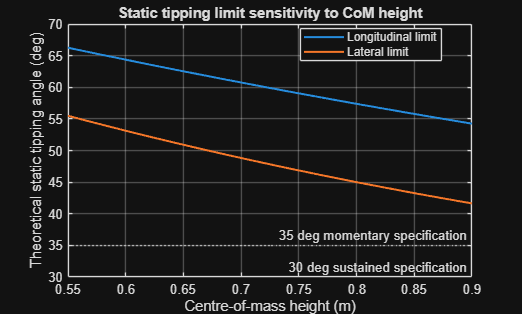


h_range = linspace(0.55, 0.90, 200);
theta_long_range = atan((L/2)./h_range);
theta_lat_range = atan((B/2)./h_range);

figure;
plot(h_range, rad2deg(theta_long_range), 'LineWidth', 1.5); hold on;
plot(h_range, rad2deg(theta_lat_range), 'LineWidth', 1.5);
yline(30, '--', '30 deg sustained specification');
yline(35, ':', '35 deg momentary specification');
xlabel('Centre-of-mass height (m)');
ylabel('Theoretical static tipping angle (deg)');
title('Static tipping limit sensitivity to CoM height');
legend('Longitudinal limit','Lateral limit','Location','best');
grid on;

## 4. Wheel reaction loads on slopes

Rigid chassis, centred CoM, equal left/right distribution for a longitudinal slope, and equal front/rear distribution for a lateral slope.

theta_deg = [0 15 30 35]';
theta = deg2rad(theta_deg);
W_total = m_max * g;

long_downhill_axle = W_total/2 .* cos(theta) + W_total*h_CoM/L .* sin(theta);
long_uphill_axle = W_total/2 .* cos(theta) - W_total*h_CoM/L .* sin(theta);
lat_downhill_side = W_total/2 .* cos(theta) + W_total*h_CoM/B .* sin(theta);
lat_uphill_side = W_total/2 .* cos(theta) - W_total*h_CoM/B .* sin(theta);

slope_table = table(theta_deg, long_downhill_axle/2, long_uphill_axle/2, ...
    lat_downhill_side/2, lat_uphill_side/2, ...
    'VariableNames', {'slope_deg','long_downhill_wheel_N', ...
    'long_uphill_wheel_N','lat_downhill_wheel_N','lat_uphill_wheel_N'});
disp(slope_table);

    slope_deg    long_downhill_wheel_N    long_uphill_wheel_N    lat_downhill_wheel_N    lat_uphill_wheel_N
    _________    _____________________    ___________________    ____________________    __________________

        0               1066.8                  1066.8                  1066.8                 1066.8      
       15               1185.1                  875.86                  1272.1                 788.88      
       30               1222.6                  625.19                  1390.6                 457.17      
       35               1216.6                  531.23                  1409.3                 338.48      



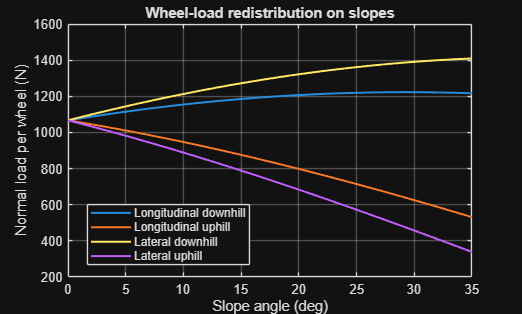


theta_plot = linspace(0,35,150);
tp = deg2rad(theta_plot);
long_down_plot = W_total/4 .* cos(tp) + W_total*h_CoM/(2*L) .* sin(tp);
long_up_plot = W_total/4 .* cos(tp) - W_total*h_CoM/(2*L) .* sin(tp);
lat_down_plot = W_total/4 .* cos(tp) + W_total*h_CoM/(2*B) .* sin(tp);
lat_up_plot = W_total/4 .* cos(tp) - W_total*h_CoM/(2*B) .* sin(tp);

figure;
plot(theta_plot,long_down_plot,'LineWidth',1.5); hold on;
plot(theta_plot,long_up_plot,'LineWidth',1.5);
plot(theta_plot,lat_down_plot,'LineWidth',1.5);
plot(theta_plot,lat_up_plot,'LineWidth',1.5);
xlabel('Slope angle (deg)');
ylabel('Normal load per wheel (N)');
title('Wheel-load redistribution on slopes');
legend('Longitudinal downhill','Longitudinal uphill', ...
       'Lateral downhill','Lateral uphill','Location','best');
grid on;

## 5. Ground pressure

Nominal contact patch: 0.25 m x 0.15 m per wheel. This is the least certain input and must be replaced by tyre data.

flat_wheel_load = W_total/4;
p_flat = flat_wheel_load/A_contact;

fprintf('Nominal contact area per wheel: %.4f m^2\n', A_contact);

Nominal contact area per wheel: 0.0375 m^2


fprintf('Flat-ground pressure at 435 kg: %.2f kPa\n', p_flat/1000);

Flat-ground pressure at 435 kg: 28.45 kPa


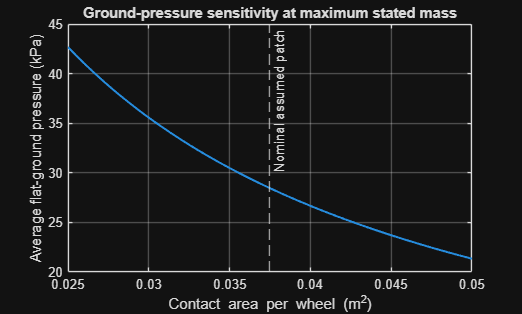


A_range = linspace(0.025,0.050,100);
p_range = flat_wheel_load ./ A_range;

figure;
plot(A_range,p_range/1000,'LineWidth',1.5);
xline(A_contact,'--','Nominal assumed patch');
xlabel('Contact area per wheel (m^2)');
ylabel('Average flat-ground pressure (kPa)');
title('Ground-pressure sensitivity at maximum stated mass');
grid on;

## 6. Traction requirement on stated grades

Neglecting rolling resistance, the minimum friction coefficient for constant-speed climbing is approximately tan(theta).

mu_30 = tand(30);
mu_35 = tand(35);
fprintf('Minimum ideal friction coefficient at 30 deg: %.3f\n', mu_30);

Minimum ideal friction coefficient at 30 deg: 0.577


fprintf('Minimum ideal friction coefficient at 35 deg: %.3f\n', mu_35);

Minimum ideal friction coefficient at 35 deg: 0.700


## 7. Engineering conclusions

fprintf('\nKEY FINDINGS\n');


KEY FINDINGS


fprintf('1. Counter-rotation gives a zero centre-path radius, but the 3.45 m x 1.88 m body\n');

1. Counter-rotation gives a zero centre-path radius, but the 3.45 m x 1.88 m body


fprintf('   sweeps a %.2f m diameter circle.\n', 2*body_swept_radius);

   sweeps a 3.93 m diameter circle.


fprintf('2. Lateral static tipping governs at %.1f deg, versus %.1f deg longitudinally.\n', ...
    rad2deg(theta_lat), rad2deg(theta_long));

2. Lateral static tipping governs at 48.8 deg, versus 60.8 deg longitudinally.


fprintf('3. Both static limits exceed the stated 30 deg sustained grade; traction, wheel slip,\n');

3. Both static limits exceed the stated 30 deg sustained grade; traction, wheel slip,


fprintf('   suspension travel and terrain irregularity are therefore more likely to govern.\n');

   suspension travel and terrain irregularity are therefore more likely to govern.


fprintf('4. At 30 deg lateral slope, the uphill wheel load falls to approximately %.0f N per wheel.\n', ...
    lat_uphill_side(theta_deg==30)/2);

4. At 30 deg lateral slope, the uphill wheel load falls to approximately 457 N per wheel.


fprintf('5. Nominal flat-ground pressure is %.1f kPa, but contact-patch uncertainty gives a\n');

5. Nominal flat-ground pressure is 

fprintf('   range of approximately %.1f to %.1f kPa.\n', ...
    flat_wheel_load/0.050/1000, flat_wheel_load/0.025/1000);

   range of approximately 21.3 to 42.7 kPa.
